# Selecting an optimal parametric model for fitting a dipolar signals

#### Author: Luis Fabregas

In this tutorial we will show how to optimally select a parametric model for a given dipolar signal.

## Simulating a dipolar signal

Let's start by constructing a simple dipolar signal with some noise arising from a bimodal Gaussian distance distribution.

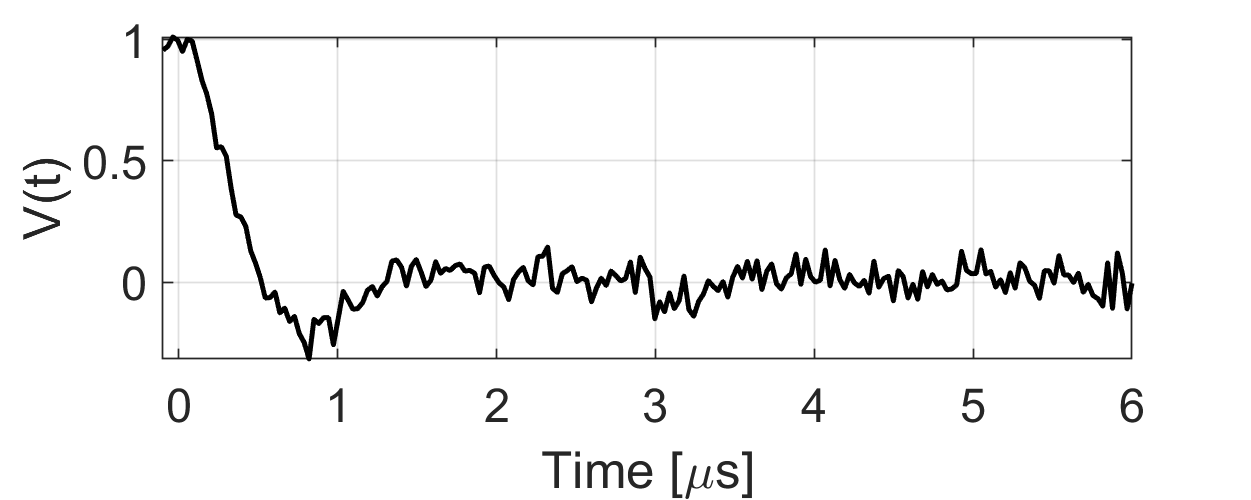

clear,clc,clf

%Prepare the signal components
t = linspace(-0.1,6,200);
r = linspace(2,8,200);
P = rd_twogaussian(r,[4 0.2 4.5 0.4 0.5]);

%Simulate the signal
V = dipolarsignal(t,r,P,'noiselevel',0.05);

%Plot
figure('position',[0 0 500 200])
plot(t,V,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('Time [\mus]'),ylabel('V(t)')

## Selecting the optimal model

Even though we know the ground truth, in this example we will cosider the following set of potential parametric models: 

- Unimodal Rician distribution

- Bimodal Rician distribution

- Trimodal Rician distribution

- Unimodal Gaussian distribution

- Bimodal Gaussian distribution

- Trimodal Gaussian distribution

- Mixed bimodal Gaussian/Rician distribution

The first six models have built-in parametric models which we can use directly. The last model we can construct from built-in models using the `mixmodels` function.

As expected the AIC criterion identifies the bimodal Gaussian model as the optimal one. The successful identification is facilitated by the relatively low noise level in the signal. However, for different noise realization this may fail.

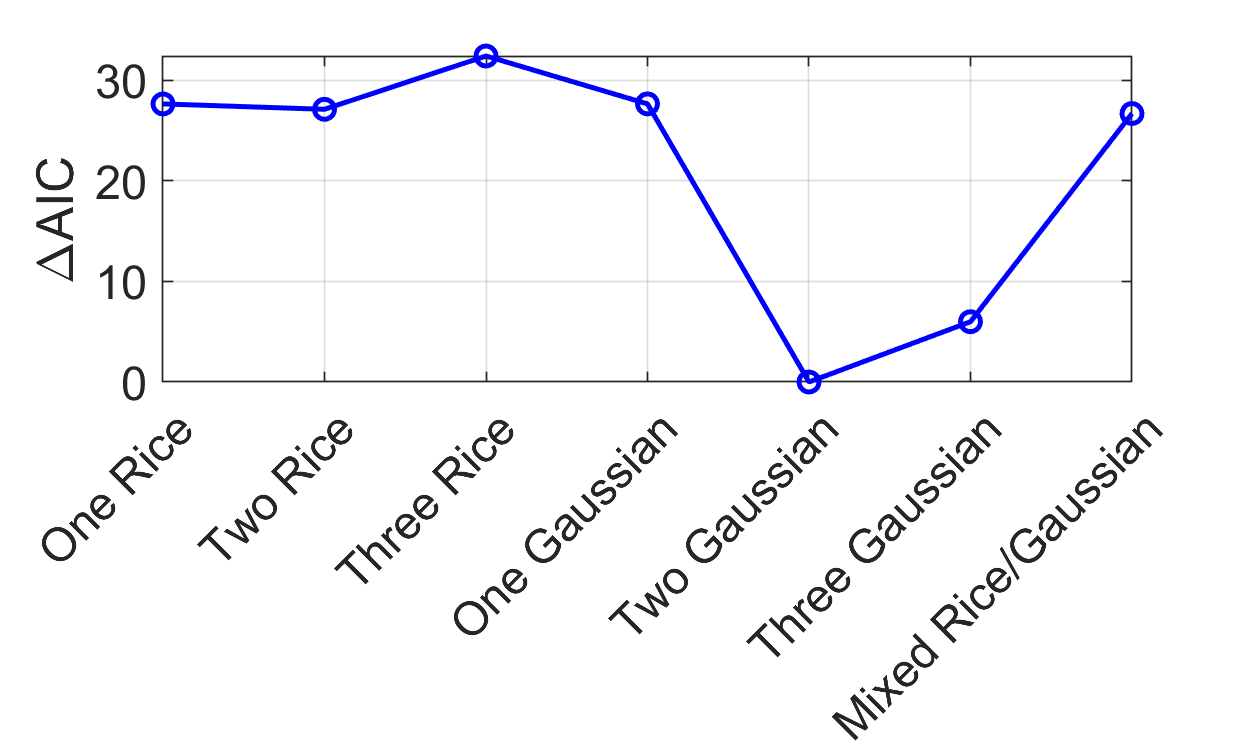

%Prepare the mixed model
rd_onerice_onegauss = mixmodels({@rd_onerice,@rd_onegaussian});

%Prepare list of candidate parametric models
Models = {@rd_onerice,@rd_tworice,@rd_threerice,...
          @rd_onegaussian,@rd_twogaussian,@rd_threegaussian,rd_onerice_onegauss};
     
%Prepare the dipolar kernel
K = dipolarkernel(t,r);

%Optimize the selection
[optIdx,metric] = selectmodel(Models,V,r,K,'aic');

%Plot the results
figure('position',[0 0 500 300])
clf,hold on
plot(metric - min(metric),'b-o','LineWidth',1.5)
grid on, box on,axis tight
ylabel('\DeltaAIC')
tags = {'One Rice','Two Rice','Three Rice','One Gaussian','Two Gaussian','Three Gaussian','Mixed Rice/Gaussian'};
set(gca,'xtick',1:length(Models),'xticklabel',tags,'fontsize',14)
xtickangle(45)